# Show renders from our lenses

This script allows you to visualize in advance how a scene will render through some or all of our current lenses for a user-selected sensor size. By default it will use all of the lens files in your path, but you can filter for those containing a specific string in their name.

Dependencies: ISET3d-v4, ISETCam, isetlens

D. Cardinal, 2022

Note: For expediency, we have pre-generated several possible variations of scene and sensor size and placed them as HTML files in the previews sub-folder.

## Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

## Choose Options

sensorSize =6; % (diagonal in mm)
useScene = 'chessSet'; % one of our default scenes
raysPerPixel = 96;
sensorResolution = 400;
% optionally only render matching lenses
lensNameFilter = "";

fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 6, rayPP 96, resolution 400


## Read the selected Scene and add a Light

thisR  = piRecipeDefault('scene name',useScene);

Read 9 materials and 3 textures..


lightName = 'from camera';
ourLight = piLightCreate(lightName,...
    'type','distant',...
    'cameracoordinate', true);
recipeSet(thisR,'lights', ourLight,'add');

## Set render quality

% Set resolution for speed or quality.
thisR.set('film resolution',[sensorResolution sensorResolution]);  % 2 is high res. 0.25 for speed
thisR.set('rays per pixel',raysPerPixel);                      % 128 for high quality

% Pick out a bit of the image to look at.  Middle dimension is up.
% Third dimension is z.  For the chess set we use a from/to that put the ruler in the
% middle.  The in focus is about the pawn or rook.
switch(useScene)
    case 'chessSet'
        thisR.set('from',[0 0.14 -0.7]);     % Get higher and back away than default
        thisR.set('to',  [0.05 -0.07 0.5]);  % Look down default compared to default
    case 'cornell_box'
        %
end
%thisR.set('aperture diameter',1);   % thisR.summarize('all');

## Determine the range of object depths in our scene

Note: Getting depth will use pinhole optics, but we use an omni camera with lenses for the rest.

depthRange = thisR.get('depth range');

*** Rendering time for ChessSet:  8.6 sec ***

exr2bin done.

%depthRange = [0.1674, 3.3153];  % Chess set distances in meters

## Create cameras that use each lens

We get a list of all our lenses, then iterate over it creating a camera object using that lens, and render the same scene through each of them.

allLensFiles = lensC.list('quiet', true);
if ~isempty(lensNameFilter)
    lensNames = {allLensFiles.name};
    lensIdx = contains(lensNames,lensNameFilter);
    lensFiles = allLensFiles(lensIdx);
else
    lensFiles = allLensFiles;
end
images = []; % our output images
for ii = 1:numel(lensFiles)
    lensFileName = lensFiles(ii).name;
    lensFile = fullfile(lensFiles(ii).folder, lensFileName);
    fprintf('Using lens #%d: %s\n',ii, lensFile);
    thisR.camera = piCameraCreate('omni','lensFile',lensFile);
    thisR.set('focal distance',mean(depthRange));
    
    % depending on the film size we'll get
    % different fields of view
    thisR.set('film diagonal',sensorSize);

## Render and display

Using lens #1: C:\iset\isetlens\data\lens\2ElLens.json


*** Rendering time for ChessSet:  12.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\2ElLens.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\2ElLens.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\2ElLens.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\2ElLens.json


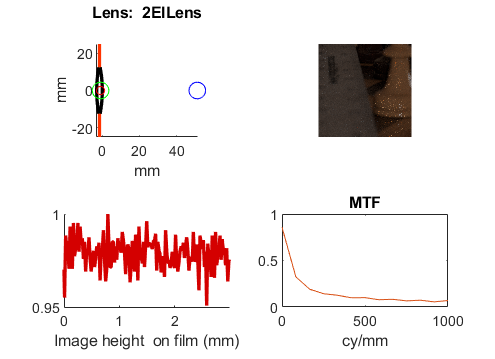

Using lens #2: C:\iset\isetlens\data\lens\2el.XXdeg.100mm.json


*** Rendering time for ChessSet:  11.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.7 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.

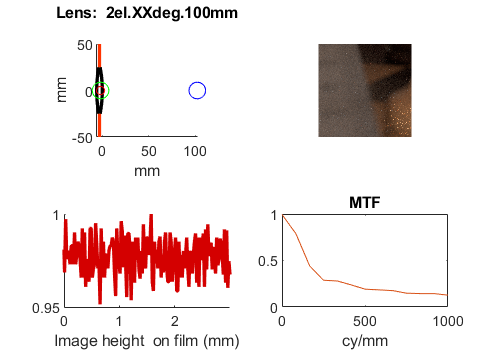

Using lens #3: C:\iset\isetlens\data\lens\2el.XXdeg.12mm.json


*** Rendering time for ChessSet:  11.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.3 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.

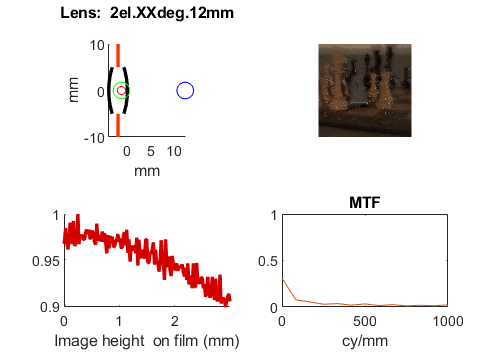

Using lens #4: C:\iset\isetlens\data\lens\2el.XXdeg.50mm.json


*** Rendering time for ChessSet:  11.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.

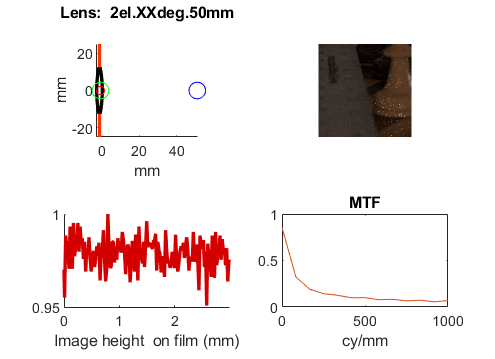

Using lens #5: C:\iset\isetlens\data\lens\2el.XXdeg.6.0mm.json


*** Rendering time for ChessSet:  10.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  7.8 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.5 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.

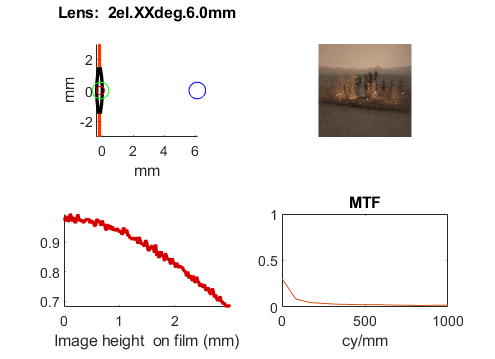

Using lens #6: C:\iset\isetlens\data\lens\dgauss.22deg.100.0mm.json


*** Rendering time for ChessSet:  13.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.2 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.1 sec ***

exr2bin done.

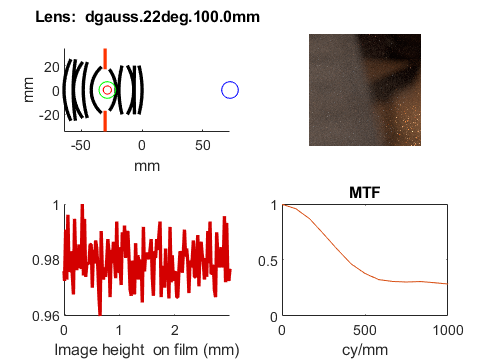

Using lens #7: C:\iset\isetlens\data\lens\dgauss.22deg.12.5mm.json


*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.1 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.

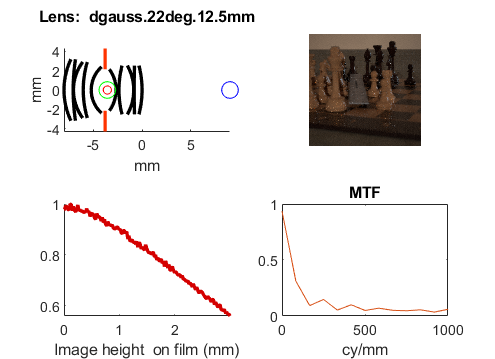

Using lens #8: C:\iset\isetlens\data\lens\dgauss.22deg.3.0mm.json


*** Rendering time for ChessSet:  10.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.0 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.

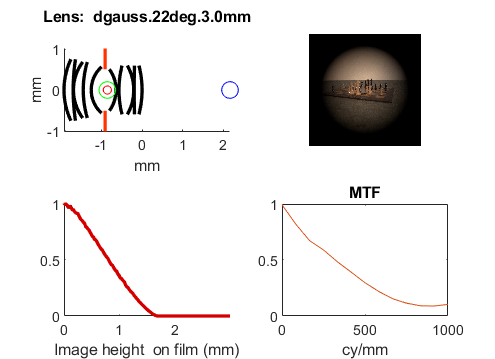

Using lens #9: C:\iset\isetlens\data\lens\dgauss.22deg.50.0mm.json


*** Rendering time for ChessSet:  13.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.6 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.1 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.6 sec ***

exr2bin done.

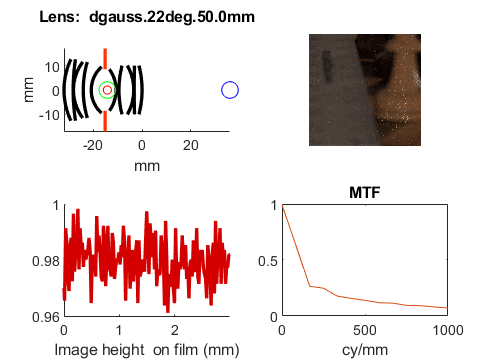

Using lens #10: C:\iset\isetlens\data\lens\dgauss.22deg.6.0mm.json


*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.3 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.3 sec ***

exr2bin done.

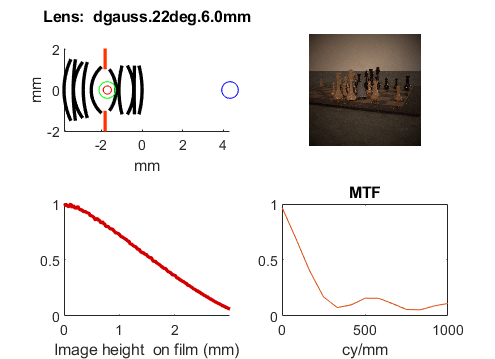

Using lens #11: C:\iset\isetlens\data\lens\dgauss.22deg.6.0mm_v3.json


*** Rendering time for ChessSet:  11.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.

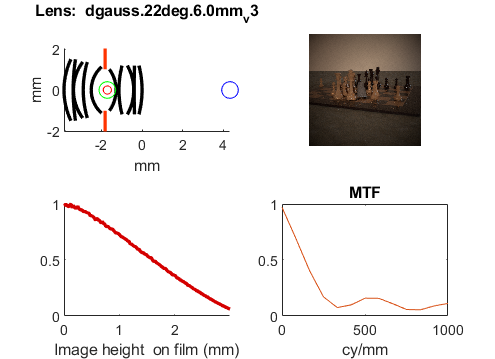

Using lens #12: C:\iset\isetlens\data\lens\dgauss.77deg.3.5201mm.json


*** Rendering time for ChessSet:  11.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\dgauss.77deg.3.5201mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\dgauss.77deg.3.5201mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.7 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\dgauss.77deg.3.5201mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\dgauss.77deg.3.5201mm.json


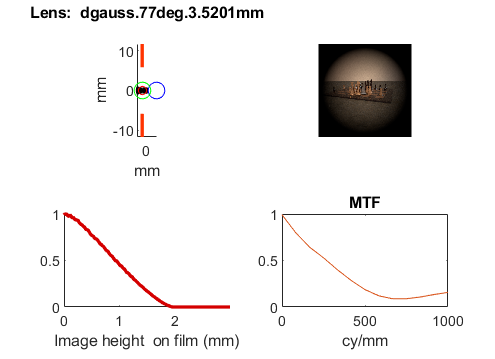

Using lens #13: C:\iset\isetlens\data\lens\endoscope.json


Status:
     1

Result:
pbrt version 4 (built Mar  4 2022 at 18:17:19)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.9 sec ***



Using lens #14: C:\iset\isetlens\data\lens\endoscopeFixed.json


Status:
     1

Result:
pbrt version 4 (built Mar  4 2022 at 18:17:19)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.5 sec ***



Using lens #15: C:\iset\isetlens\data\lens\fisheye.87deg.100.0mm.json


*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.6 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.100.0mm.json


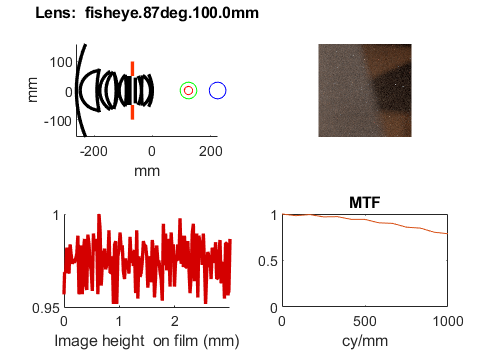

Using lens #16: C:\iset\isetlens\data\lens\fisheye.87deg.12.5mm.json


*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.5 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.0 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.12.5mm.json


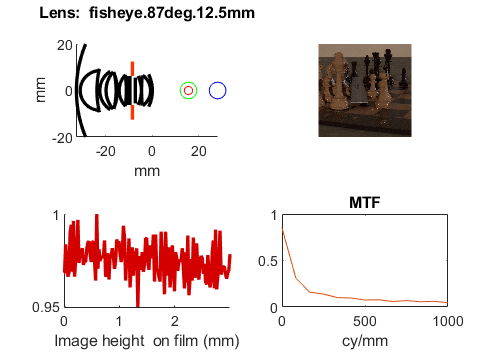

Using lens #17: C:\iset\isetlens\data\lens\fisheye.87deg.3.0mm.json


*** Rendering time for ChessSet:  10.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.3.0mm.json


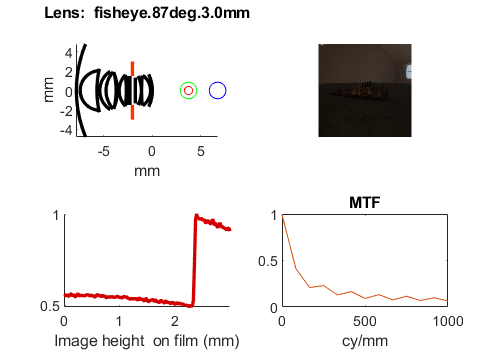

Using lens #18: C:\iset\isetlens\data\lens\fisheye.87deg.50.0mm.json


*** Rendering time for ChessSet:  13.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.2 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.50.0mm.json


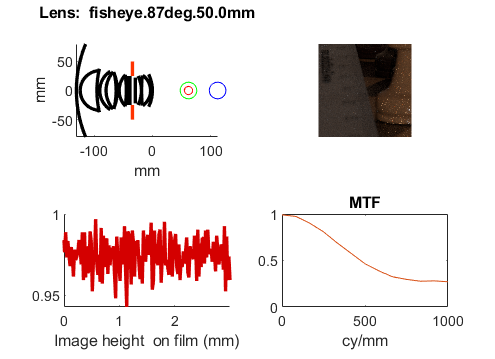

Using lens #19: C:\iset\isetlens\data\lens\fisheye.87deg.6.0mm.json


*** Rendering time for ChessSet:  11.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\fisheye.87deg.6.0mm.json


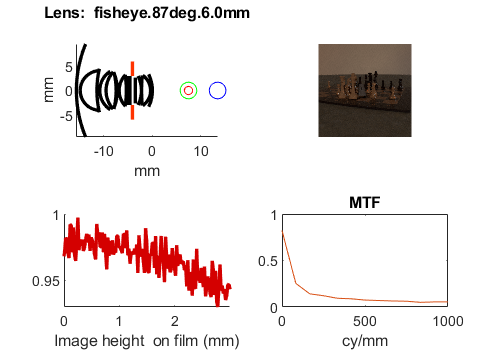

Using lens #20: C:\iset\isetlens\data\lens\gullstrand.json


*** Rendering time for ChessSet:  11.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\gullstrand.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\gullstrand.json


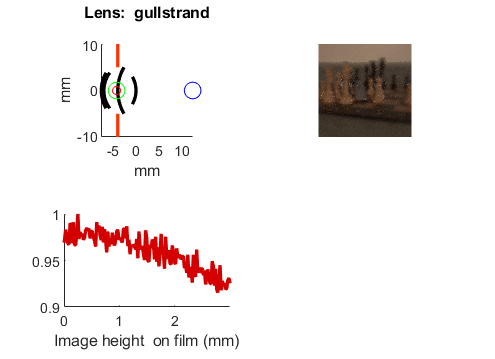

Render Camera 1 position 1
Read 0 materials and 0 textures.


Status:
     1

Result:
pbrt version 4 (built Mar  4 2022 at 18:17:19)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from film to scene for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for stepfunction:  3.7 sec ***



Using lens #21: C:\iset\isetlens\data\lens\microlens.json


Status:
     1

Result:
pbrt version 4 (built Mar  4 2022 at 18:17:19)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Unable to trace ray from scene to film for thick lens approximation. Is aperture stop extremely small?

*** Rendering time for ChessSet:  3.9 sec ***



Using lens #22: C:\iset\isetlens\data\lens\petzval.12deg.100.0mm.json


*** Rendering time for ChessSet:  12.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.0 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.100.0mm.json


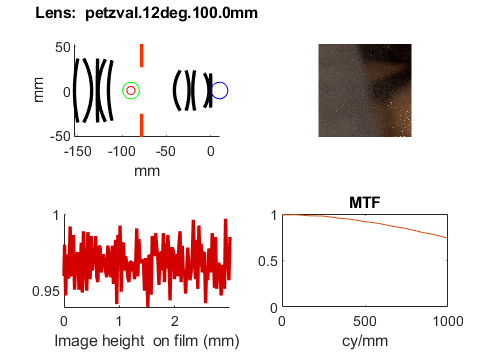

Using lens #23: C:\iset\isetlens\data\lens\petzval.12deg.12.5mm.json


*** Rendering time for ChessSet:  12.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.3 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.6 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.12.5mm.json


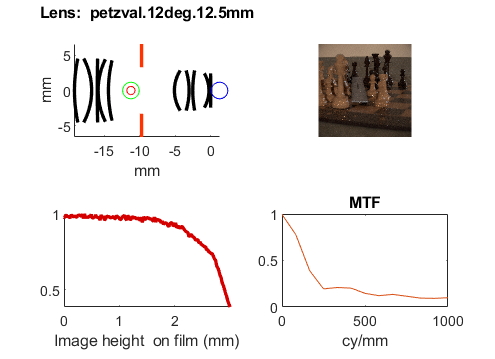

Using lens #24: C:\iset\isetlens\data\lens\petzval.12deg.3.0mm.json


*** Rendering time for ChessSet:  9.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.7 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.6 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.3.0mm.json


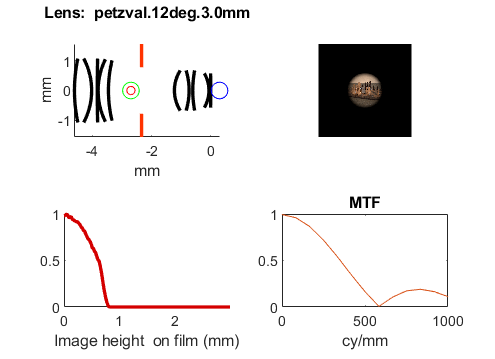

Using lens #25: C:\iset\isetlens\data\lens\petzval.12deg.50.0mm.json


*** Rendering time for ChessSet:  11.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.6 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.50.0mm.json


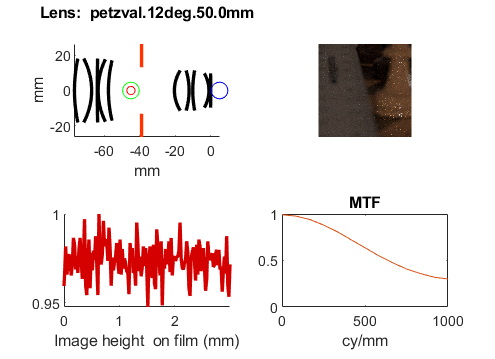

Using lens #26: C:\iset\isetlens\data\lens\petzval.12deg.6.0mm.json


*** Rendering time for ChessSet:  10.4 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  11.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\petzval.12deg.6.0mm.json


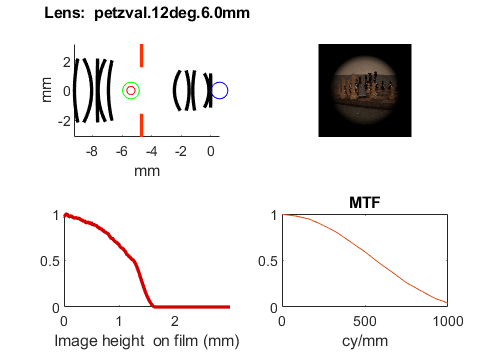

Using lens #27: C:\iset\isetlens\data\lens\reversed.telephoto.42deg.27mm.json


*** Rendering time for ChessSet:  13.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.27mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.27mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.6 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.27mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.5 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.27mm.json


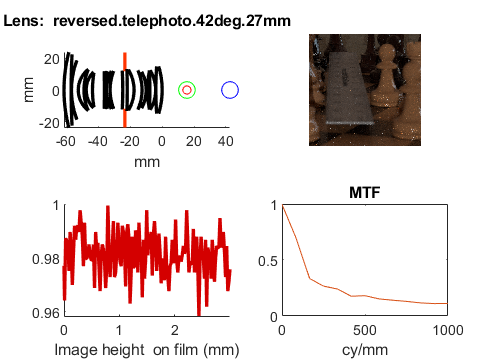

Using lens #28: C:\iset\isetlens\data\lens\reversed.telephoto.42deg.3.5201mm.json


*** Rendering time for ChessSet:  10.8 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.3.5201mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.3.5201mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.3.5201mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.42deg.3.5201mm.json


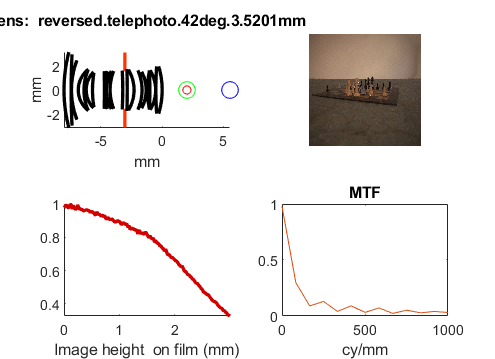

Using lens #29: C:\iset\isetlens\data\lens\reversed.telephoto.77deg.3.5201mm.json


*** Rendering time for ChessSet:  10.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.77deg.3.5201mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.77deg.3.5201mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.77deg.3.5201mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\isetlens\data\lens\reversed.telephoto.77deg.3.5201mm.json


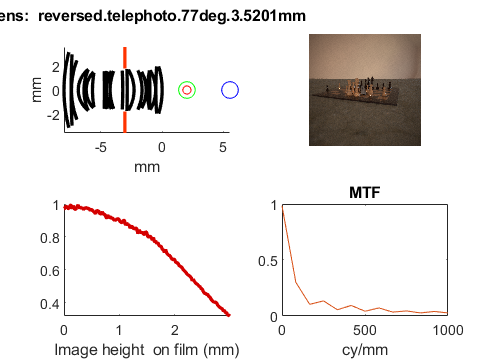

Using lens #30: C:\iset\isetlens\data\lens\telephoto.250mm.json


Status:
     1

Result:
pbrt version 4 (built Mar  4 2022 at 18:17:19)
Copyright (c)1998-2021 Matt Pharr, Wenzel Jakob, and Greg Humphreys.
The source code to pbrt (but *not* the book contents) is covered by the Apache 2.0 License.
See the file LICENSE.txt for the conditions of the license.
Error: Coefficient must be positive. It looks focusDistance 1  is too short for a given lenses configuration

*** Rendering time for ChessSet:  3.5 sec ***



Using lens #31: C:\iset\isetlens\data\lens\tessar.22deg.100.0mm.json


*** Rendering time for ChessSet:  12.2 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.4 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.7 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.9 sec ***

exr2bin done.

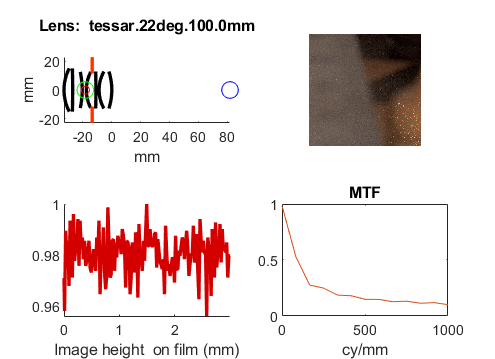

Using lens #32: C:\iset\isetlens\data\lens\tessar.22deg.12.5mm.json


*** Rendering time for ChessSet:  11.9 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.2 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.6 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.

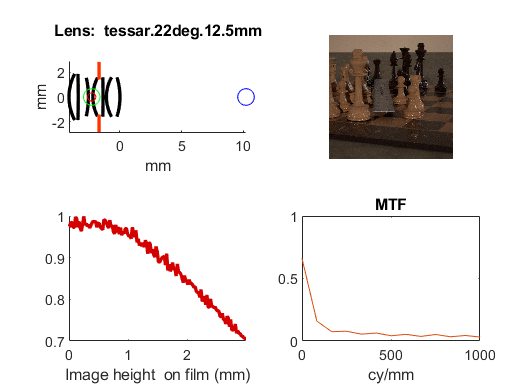

Using lens #33: C:\iset\isetlens\data\lens\tessar.22deg.3.0mm.json


*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.7 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.9 sec ***

exr2bin done.

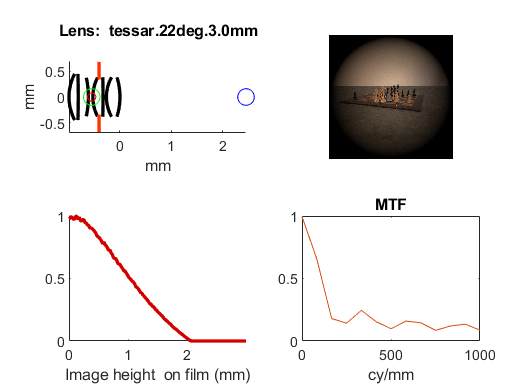

Using lens #34: C:\iset\isetlens\data\lens\tessar.22deg.50.0mm.json


*** Rendering time for ChessSet:  13.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  10.2 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.3 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.6 sec ***

exr2bin done.

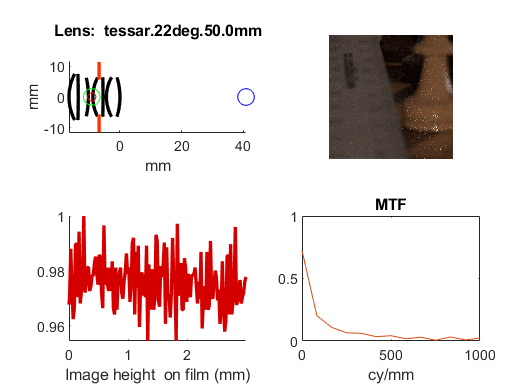

Using lens #35: C:\iset\isetlens\data\lens\tessar.22deg.6.0mm.json


*** Rendering time for ChessSet:  12.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.

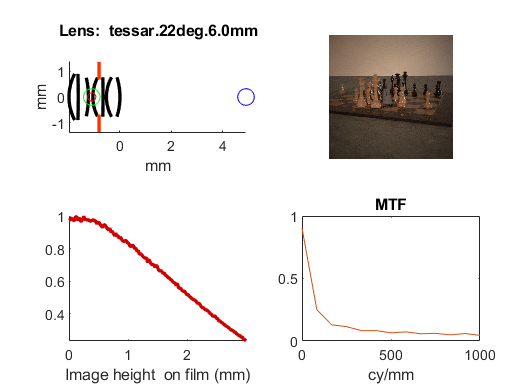

Using lens #36: C:\iset\isetlens\data\lens\wide.40deg.100.0mm.json


*** Rendering time for ChessSet:  10.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.

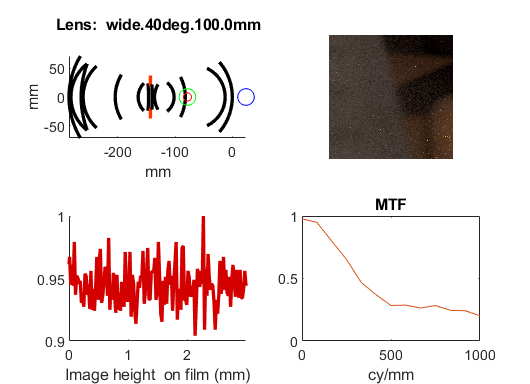

Using lens #37: C:\iset\isetlens\data\lens\wide.40deg.12.5mm.json


*** Rendering time for ChessSet:  11.1 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.3 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.

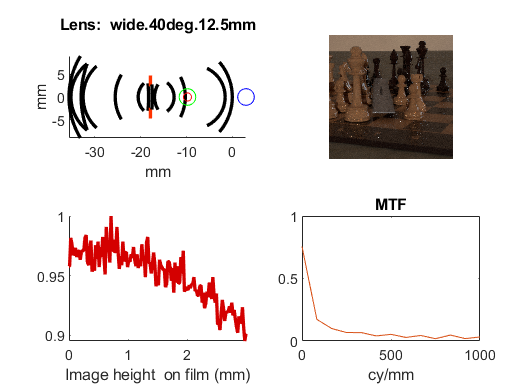

Using lens #38: C:\iset\isetlens\data\lens\wide.40deg.3.0mm.json


*** Rendering time for ChessSet:  10.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.6 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.6 sec ***

exr2bin done.

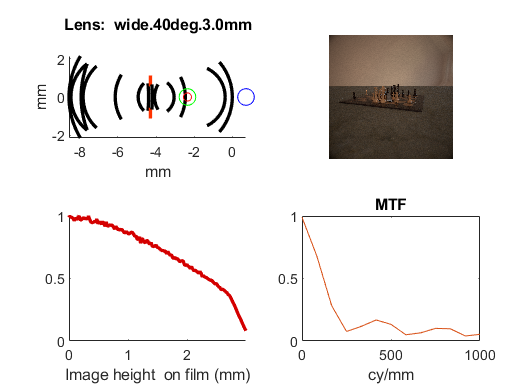

Using lens #39: C:\iset\isetlens\data\lens\wide.40deg.50.0mm.json


*** Rendering time for ChessSet:  10.7 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.6 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.

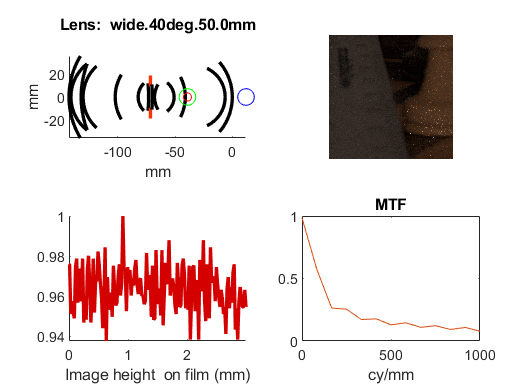

Using lens #40: C:\iset\isetlens\data\lens\wide.40deg.6.0mm.json


*** Rendering time for ChessSet:  10.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.9 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  8.8 sec ***

exr2bin done.

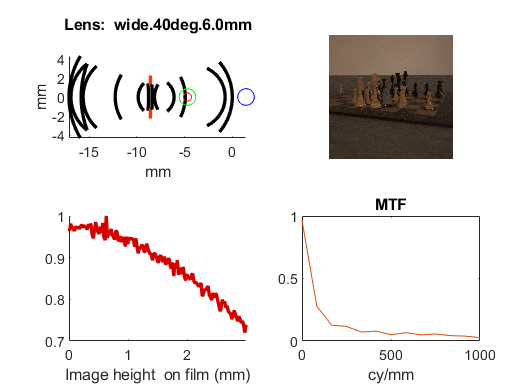

Using lens #41: C:\iset\isetlens\data\lens\wide.56deg.100.0mm.json


*** Rendering time for ChessSet:  11.0 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.6 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.4 sec ***

exr2bin done.

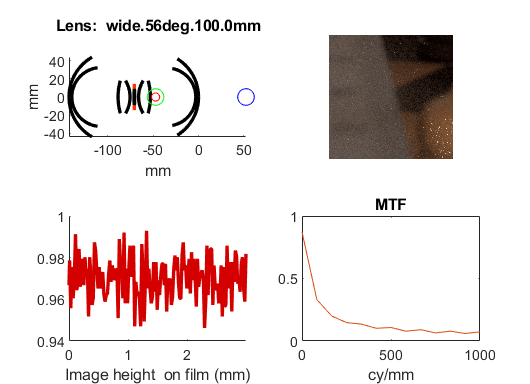

Using lens #42: C:\iset\isetlens\data\lens\wide.56deg.12.5mm.json


*** Rendering time for ChessSet:  11.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.2 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.

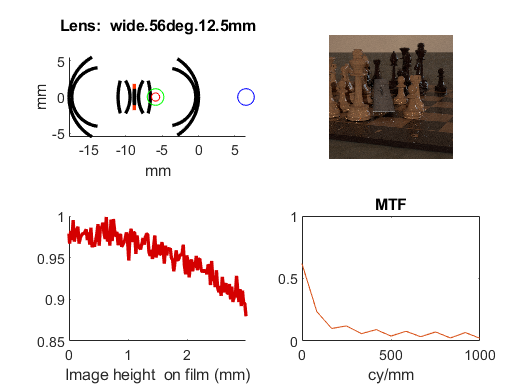

Using lens #43: C:\iset\isetlens\data\lens\wide.56deg.3.0mm.json


*** Rendering time for ChessSet:  10.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.5 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.0 sec ***

exr2bin done.

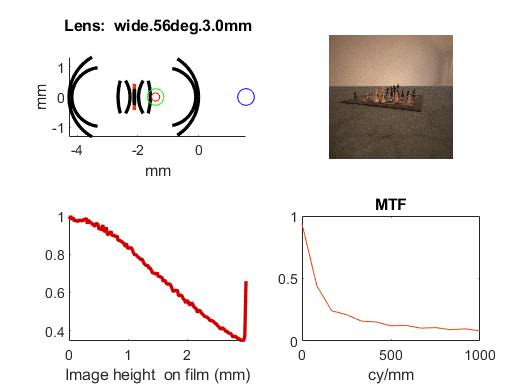

Using lens #44: C:\iset\isetlens\data\lens\wide.56deg.50.0mm.json


*** Rendering time for ChessSet:  12.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.7 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.2 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  10.5 sec ***

exr2bin done.

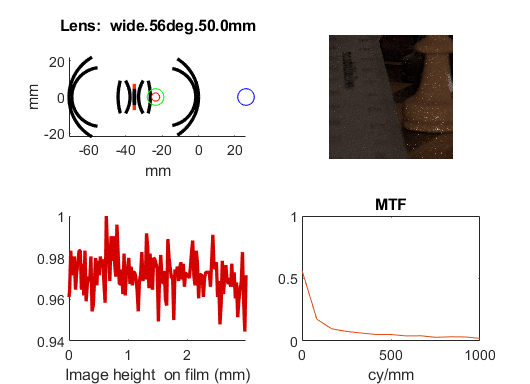

Using lens #45: C:\iset\isetlens\data\lens\wide.56deg.6.0mm.json


*** Rendering time for ChessSet:  11.3 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.8 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.3 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.2 sec ***

exr2bin done.

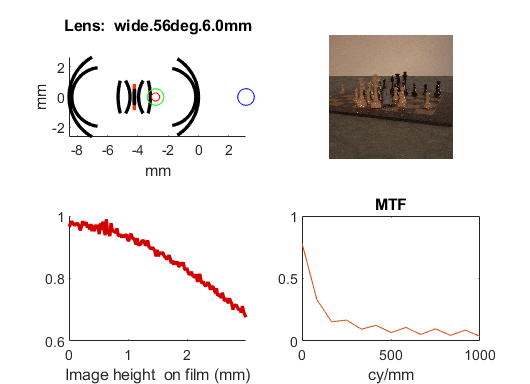

Using lens #46: C:\iset\isetlens\data\lens\wide.56deg.6.0mm_v3.json


*** Rendering time for ChessSet:  11.6 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.

Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  8.8 sec ***

exr2bin done.

Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.2 sec ***

exr2bin done.Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.5 sec ***

exr2bin done.

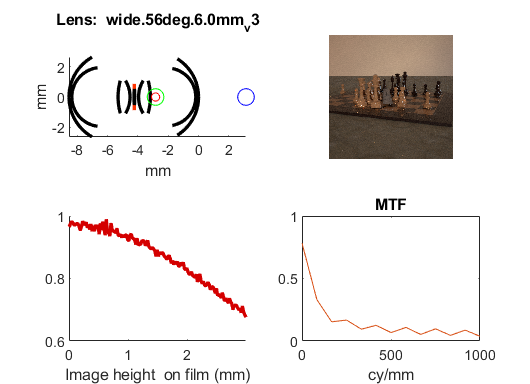

Using lens #47: C:\iset\isetlens\data\lens\wide.77deg.4.38mm.json


*** Rendering time for ChessSet:  11.5 sec ***

exr2bin done.exr2bin done.exr2bin done.exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Read 2 materials and 0 textures..
*** Rendering time for flatSurface:  9.2 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


Render Camera 1 position 1
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json
Render Camera 1 position 2
Read 0 materials and 0 textures.
*** Rendering time for stepfunction:  9.1 sec ***

exr2bin done.Decoding lens parameters from lens file name C:\iset\iset3d-v4\data\lens\wide.77deg.4.38mm.json


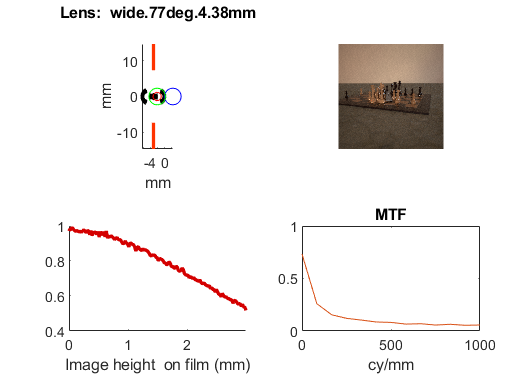

    piWrite(thisR);
    
    try
        oi = piRender(thisR,'render type',{'radiance', 'depth'});
        oi = oiSet(oi,'name',sprintf('Lens: %s  and %d mm sensor',...
            lensFileName, sensorSize));
        % get a viewable version of our optical image:
        img = oiShowImage(oi,-1);
        
        % Load our lens so we can view it
        lenses{ii} = lensC('filename', lensFile);
        
        % Set some headers per lens
        %fprintf('----------------------------\n');
        %fprintf('Rendered using: %s, with focal length: %05.1f',lensFileName,lenses{ii}.focalLength);
        
        % Draw a diagram of our lens into a subplot
        [~,fHdl] = lenses{ii}.draw([2,2,1]);
        
        images{ii} = img; % for creating a montage at the end of the script
        
        % show sample output in our subplot
        subplot(2,2,2);
        imshow(img,'Border','tight');
        
        % plot relative illuminance (into a subplot)
        piRelativeIlluminance("lensfile",lensFile,"figure",[2,2,3],...
            'sensorSize',sensorSize, 'focalDistance', thisR.get('focal distance'));

        % plot MTF
        %filmwidth_mm=0.01;
        filmwidth_mm=.01;
        [MTF, ~, ~] = piCalculateMTF('camera',thisR.camera,...
            'distances',depthRange,...
            'resolution',2000,'rays',1000,...
            'filmwidth', sensorSize/1000);
        subplot(224);
        plot(MTF.cyclespermilimeter,MTF.MTF);
        xlabel('cy/mm');
        ylim([0 1]);
        xlim([0 1000]);
        title('MTF');

        % set plot attributes
        set(gcf,'Name',lensFileName,'MenuBar','none','ToolBar','none');

        drawnow; %doesn't seem to help, but who knows?
        % footer if using headers
        %fprintf('----------------------------\n');

    catch
        warning('Lens: %s failed to render.\n', lensFile);
    end
    
end

## Show a Captioned Montage for Reference

For filename captions to be legible we need to make sure we have enough room

minTileSize = 400; thumbnailSize = 400;
boxSize = max(minTileSize, sensorResolution);
textPosition = [10 10; boxSize-30 boxSize-30];
for ii = 1:numel(images)
    if minTileSize > sensorResolution && ~isempty(images{ii})
        imagesR{ii} = imresize(images{ii},[boxSize boxSize]);
    else
        imagesR{ii} = images{ii};
    end
    imagesC{ii} = insertText(imagesR{ii}, textPosition, lensFiles(ii).name, ...
        'FontSize', 36); %#ok<*SAGROW>
end
figure; % new figure below 
fprintf('Lens Inventory using Scene: %s\n', useScene);

Lens Inventory using Scene: chessSet


fprintf('Sensor Size: %d, rayPP %d, resolution %d\n',...
    sensorSize,raysPerPixel,sensorResolution);

Sensor Size: 6, rayPP 96, resolution 400


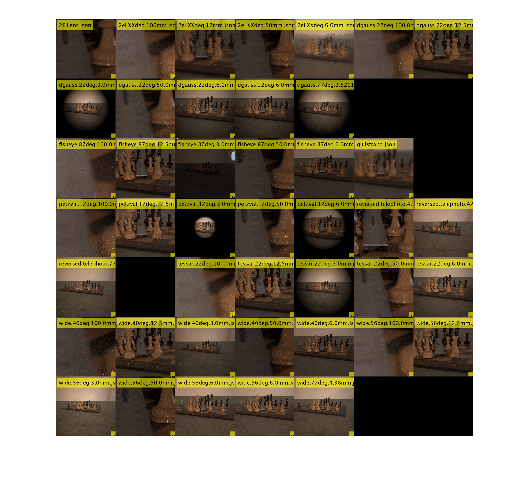

montage(imagesC,'ThumbnailSize',[thumbnailSize thumbnailSize]);